Colin Keenan

ECE 5470

3-16-2020

# Homework 7

1.  Smoothing Linear Filtering

clear

fprintf("Question 1:")

Question 1:

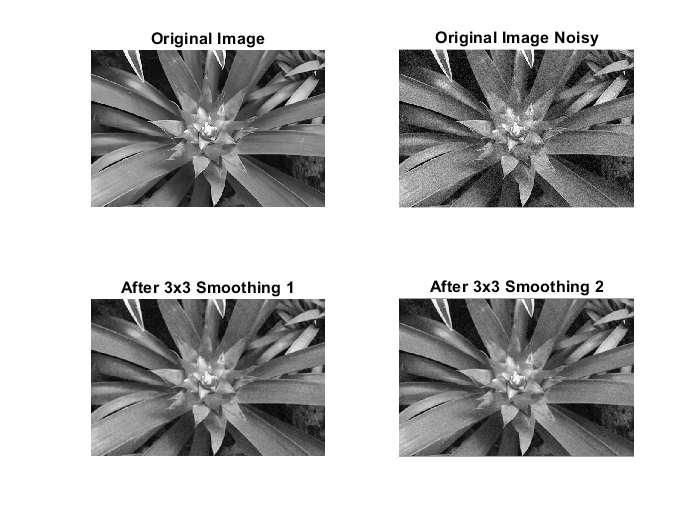


image = imread('Fig7-1a.jpg');
image_noisy = imread('Fig7-1b.jpg');
image_double = im2double(image_noisy);

image_mod_3x3_smooth1 = zeros(size(image_double));
image_mod_3x3_smooth2 = zeros(size(image_double));

mask_3x3_smooth1 = [[1 1 1]
                    [1 1 1]
                    [1 1 1]];
mask_weight_smooth1 = sum(sum(mask_3x3_smooth1));

for i = 1+1 : size(image_double,1)-1
    for j = 1+1 : size(image_double,2)-1
        
        frame_3x3 = [[image_double(i-1,j-1) image_double(i-1,j+0) image_double(i-1,j+1)]
                     [image_double(i+0,j-1) image_double(i+0,j+0) image_double(i+0,j+1)]
                     [image_double(i+1,j-1) image_double(i+1,j+0) image_double(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3_smooth1;
        image_mod_3x3_smooth1(i,j) = sum(sum(masked)) / mask_weight_smooth1;
    end
end
        
mask_3x3_smooth2 = [[1 2 1]
                    [2 4 2]
                    [1 2 1]];
mask_weight_smooth2 = sum(sum(mask_3x3_smooth2));
               
for i = 1+1 : size(image_double,1)-1
    for j = 1+1 : size(image_double,2)-1
        
        frame_3x3 = [[image_double(i-1,j-1) image_double(i-1,j+0) image_double(i-1,j+1)]
                     [image_double(i+0,j-1) image_double(i+0,j+0) image_double(i+0,j+1)]
                     [image_double(i+1,j-1) image_double(i+1,j+0) image_double(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3_smooth2;
        image_mod_3x3_smooth2(i,j) = sum(sum(masked)) / mask_weight_smooth2;
    end
end

figure();
subplot(2,2,1)
imshow(image);
title("Original Image");
subplot(2,2,2)
imshow(image_noisy);
title("Original Image Noisy");
subplot(2,2,3)
imshow(image_mod_3x3_smooth1);
title("After 3x3 Smoothing 1");
subplot(2,2,4)
imshow(image_mod_3x3_smooth2);
title("After 3x3 Smoothing 2");

Explanation: As you can see from the images, using the two different varients of 3x3 smoothing linear filters, they do not quite restore the image to its original state, but it is noticeable better than the noisy image.

2. Mean Filtering

## Arithmetic Mean Filter

clear

fprintf("Question 2, Arithmetic Mean Filter:")

Question 2, Arithmetic Mean Filter:

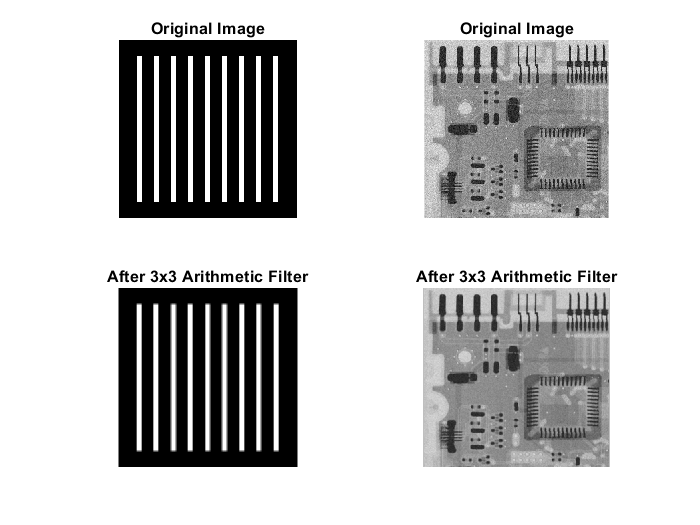


A_image = im2double(imread('Fig7-2a.tif'));
B_image = im2double(imread('Fig7-2b.tif'));

A_image_mod_3x3 = zeros(size(A_image));
B_image_mod_3x3 = zeros(size(B_image));

mask_3x3 = [[1 1 1]
            [1 1 1]
            [1 1 1]];
mask_weight = sum(sum(mask_3x3));

for i = 1+1 : size(A_image,1)-1
    for j = 1+1 : size(A_image,2)-1
        
        frame_3x3 = [[A_image(i-1,j-1) A_image(i-1,j+0) A_image(i-1,j+1)]
                     [A_image(i+0,j-1) A_image(i+0,j+0) A_image(i+0,j+1)]
                     [A_image(i+1,j-1) A_image(i+1,j+0) A_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        A_image_mod_3x3(i,j) = sum(sum(masked)) / mask_weight;
    end
end
               
for i = 1+1 : size(B_image,1)-1
    for j = 1+1 : size(B_image,2)-1
        
        frame_3x3 = [[B_image(i-1,j-1) B_image(i-1,j+0) B_image(i-1,j+1)]
                     [B_image(i+0,j-1) B_image(i+0,j+0) B_image(i+0,j+1)]
                     [B_image(i+1,j-1) B_image(i+1,j+0) B_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        B_image_mod_3x3(i,j) = sum(sum(masked)) / mask_weight;
    end
end

figure();
subplot(2,2,1)
imshow(A_image);
title("Original Image");
subplot(2,2,2)
imshow(B_image);
title("Original Image");
subplot(2,2,3)
imshow(A_image_mod_3x3);
title("After 3x3 Arithmetic Filter");
subplot(2,2,4)
imshow(B_image_mod_3x3);
title("After 3x3 Arithmetic Filter");

Explanation: As you can see in the image of the xray, the arithmetic mean filter does a good job restoring the image, but at the same time, when looking at the vertical bars, you can see some odd artifacting around the edges that seem to blur the edges from white to black.

## Geometric Mean Filter

clear

fprintf("Question 2, Geometric Mean Filter:")

Question 2, Geometric Mean Filter:

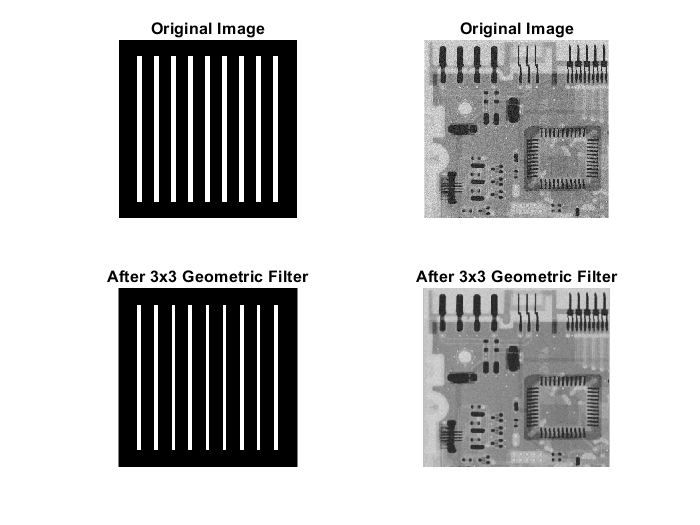


A_image = im2double(imread('Fig7-2a.tif'));
B_image = im2double(imread('Fig7-2b.tif'));

A_image_mod_3x3 = zeros(size(A_image));
B_image_mod_3x3 = zeros(size(B_image));

mask_3x3 = [[1 1 1]
            [1 1 1]
            [1 1 1]];
mask_weight = sum(sum(mask_3x3));

for i = 1+1 : size(A_image,1)-1
    for j = 1+1 : size(A_image,2)-1
        
        frame_3x3 = [[A_image(i-1,j-1) A_image(i-1,j+0) A_image(i-1,j+1)]
                     [A_image(i+0,j-1) A_image(i+0,j+0) A_image(i+0,j+1)]
                     [A_image(i+1,j-1) A_image(i+1,j+0) A_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        A_image_mod_3x3(i,j) = prod(prod(masked)) ^ (1/mask_weight);
    end
end
               
for i = 1+1 : size(B_image,1)-1
    for j = 1+1 : size(B_image,2)-1
        
        frame_3x3 = [[B_image(i-1,j-1) B_image(i-1,j+0) B_image(i-1,j+1)]
                     [B_image(i+0,j-1) B_image(i+0,j+0) B_image(i+0,j+1)]
                     [B_image(i+1,j-1) B_image(i+1,j+0) B_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        B_image_mod_3x3(i,j) = prod(prod(masked)) ^ (1/mask_weight);
    end
end

figure();
subplot(2,2,1)
imshow(A_image);
title("Original Image");
subplot(2,2,2)
imshow(B_image);
title("Original Image");
subplot(2,2,3)
imshow(A_image_mod_3x3);
title("After 3x3 Geometric Filter");
subplot(2,2,4)
imshow(B_image_mod_3x3);
title("After 3x3 Geometric Filter");

Explanation: As you can see in the image of the xray, the geometric mean filter does a comparable job of restoring the original image to the arithmetic mean filter. However in the case of the vertical bars, those odd artifacts around the edges of the vertical bars have been eliminated, but the overall thickness of the bars have been reduced.

## Harmonic Mean Filter

clear

fprintf("Question 2, Harmonic Mean Filter:")

Question 2, Harmonic Mean Filter:

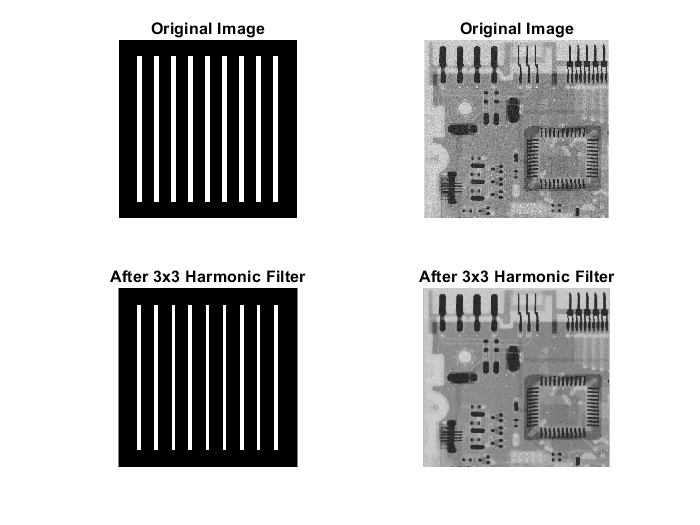


A_image = im2double(imread('Fig7-2a.tif'));
B_image = im2double(imread('Fig7-2b.tif'));

A_image_mod_3x3 = zeros(size(A_image));
B_image_mod_3x3 = zeros(size(B_image));

mask_3x3 = [[1 1 1]
            [1 1 1]
            [1 1 1]];
mask_weight = sum(sum(mask_3x3));

for i = 1+1 : size(A_image,1)-1
    for j = 1+1 : size(A_image,2)-1
        
        frame_3x3 = [[A_image(i-1,j-1) A_image(i-1,j+0) A_image(i-1,j+1)]
                     [A_image(i+0,j-1) A_image(i+0,j+0) A_image(i+0,j+1)]
                     [A_image(i+1,j-1) A_image(i+1,j+0) A_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        A_image_mod_3x3(i,j) = mask_weight / sum(sum(1./masked));
    end
end
               
for i = 1+1 : size(B_image,1)-1
    for j = 1+1 : size(B_image,2)-1
        
        frame_3x3 = [[B_image(i-1,j-1) B_image(i-1,j+0) B_image(i-1,j+1)]
                     [B_image(i+0,j-1) B_image(i+0,j+0) B_image(i+0,j+1)]
                     [B_image(i+1,j-1) B_image(i+1,j+0) B_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        B_image_mod_3x3(i,j) = mask_weight / sum(sum(1./masked));
    end
end

figure();
subplot(2,2,1)
imshow(A_image);
title("Original Image");
subplot(2,2,2)
imshow(B_image);
title("Original Image");
subplot(2,2,3)
imshow(A_image_mod_3x3);
title("After 3x3 Harmonic Filter");
subplot(2,2,4)
imshow(B_image_mod_3x3);
title("After 3x3 Harmonic Filter");

Explanation: Very similar to the geometric mean filter, the harmonic filter reduces the thickness of the vertical bars, and with the xray image, it has a similar result between all of the other tested mean filters.

3.  Contraharmonic Mean Filtering

## Q = 1.5

clear

fprintf("Question 3, Contraharmonic Mean Filter (Q = 1.5):")

Question 3, Contraharmonic Mean Filter (Q = 1.5):

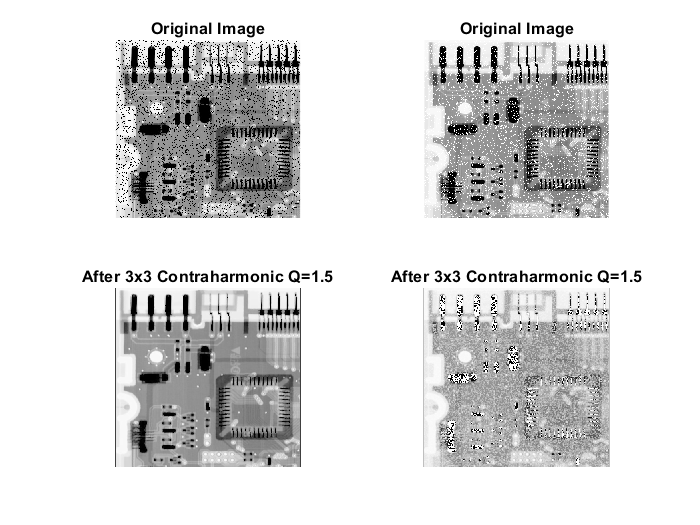


A_image = im2double(imread('Fig7-3a.tif'));
B_image = im2double(imread('Fig7-3b.tif'));
Q = 1.5;

A_image_mod_3x3 = zeros(size(A_image));
B_image_mod_3x3 = zeros(size(B_image));

mask_3x3 = [[1 1 1]
            [1 1 1]
            [1 1 1]];
mask_weight = sum(sum(mask_3x3));

for i = 1+1 : size(A_image,1)-1
    for j = 1+1 : size(A_image,2)-1
        
        frame_3x3 = [[A_image(i-1,j-1) A_image(i-1,j+0) A_image(i-1,j+1)]
                     [A_image(i+0,j-1) A_image(i+0,j+0) A_image(i+0,j+1)]
                     [A_image(i+1,j-1) A_image(i+1,j+0) A_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        A_image_mod_3x3(i,j) = sum(sum(masked.^(Q+1))) / sum(sum(masked.^(Q)));
    end
end
               
for i = 1+1 : size(B_image,1)-1
    for j = 1+1 : size(B_image,2)-1
        
        frame_3x3 = [[B_image(i-1,j-1) B_image(i-1,j+0) B_image(i-1,j+1)]
                     [B_image(i+0,j-1) B_image(i+0,j+0) B_image(i+0,j+1)]
                     [B_image(i+1,j-1) B_image(i+1,j+0) B_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        B_image_mod_3x3(i,j) = sum(sum(masked.^(Q+1))) / sum(sum(masked.^(Q)));
    end
end

figure();
subplot(2,2,1)
imshow(A_image);
title("Original Image");
subplot(2,2,2)
imshow(B_image);
title("Original Image");
subplot(2,2,3)
imshow(A_image_mod_3x3);
title("After 3x3 Contraharmonic Q=1.5");
subplot(2,2,4)
imshow(B_image_mod_3x3);
title("After 3x3 Contraharmonic Q=1.5");

Explanation: As you can see with the image with the pepper noise, the contraharmonic filter with a Q value of 1.5, it restores the image extremely well. But if you look at the image with the salt noise, and with the same Q value, it does a exceptionally poor job of restoring the image, and actually worsens the image overall.

## Q = -1.5

clear

fprintf("Question 3, Contraharmonic Mean Filter (Q = -1.5):")

Question 3, Contraharmonic Mean Filter (Q = -1.5):

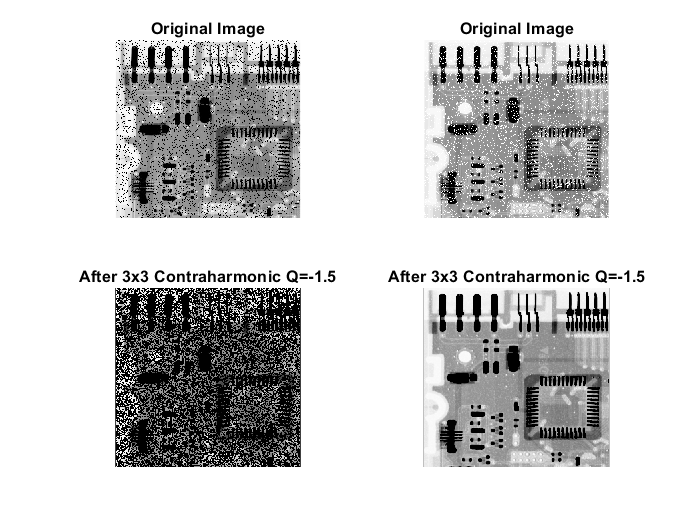


A_image = im2double(imread('Fig7-3a.tif'));
B_image = im2double(imread('Fig7-3b.tif'));
Q = -1.5;

A_image_mod_3x3 = zeros(size(A_image));
B_image_mod_3x3 = zeros(size(B_image));

mask_3x3 = [[1 1 1]
            [1 1 1]
            [1 1 1]];
mask_weight = sum(sum(mask_3x3));

for i = 1+1 : size(A_image,1)-1
    for j = 1+1 : size(A_image,2)-1
        
        frame_3x3 = [[A_image(i-1,j-1) A_image(i-1,j+0) A_image(i-1,j+1)]
                     [A_image(i+0,j-1) A_image(i+0,j+0) A_image(i+0,j+1)]
                     [A_image(i+1,j-1) A_image(i+1,j+0) A_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        A_image_mod_3x3(i,j) = sum(sum(masked.^(Q+1))) / sum(sum(masked.^(Q)));
    end
end
               
for i = 1+1 : size(B_image,1)-1
    for j = 1+1 : size(B_image,2)-1
        
        frame_3x3 = [[B_image(i-1,j-1) B_image(i-1,j+0) B_image(i-1,j+1)]
                     [B_image(i+0,j-1) B_image(i+0,j+0) B_image(i+0,j+1)]
                     [B_image(i+1,j-1) B_image(i+1,j+0) B_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        B_image_mod_3x3(i,j) = sum(sum(masked.^(Q+1))) / sum(sum(masked.^(Q)));
    end
end

figure();
subplot(2,2,1)
imshow(A_image);
title("Original Image");
subplot(2,2,2)
imshow(B_image);
title("Original Image");
subplot(2,2,3)
imshow(A_image_mod_3x3);
title("After 3x3 Contraharmonic Q=-1.5");
subplot(2,2,4)
imshow(B_image_mod_3x3);
title("After 3x3 Contraharmonic Q=-1.5");

Explanation: As you can see with the image with the salt noise, the contraharmonic filter with a Q value of -1.5, it restores the image extremely well. But if you look at the image with the pepper noise, and with the same Q value, it does a exceptionally poor job of restoring the image, and actually worsens the image overall.